# Taller 11

### 24/10/2022 2022-01S

#### Métodos Númericos

#### *Resumen sobre la semana 9 y 10*

*Notas para el uso de MATLAB:*

- Frente a las operaciones de númericas tenemos 2 definiciones distintas y es importante separarlas, las operaciones $+-*\;/$, son directas matriciales, en cambio las prefijadas con ${\prime \ldotp }^{\prime }$, son *element-wise*, o sea se realizan en cada uno de los elementos del argumento entregado a la función. Importante en la notación con @

- Si se necesita conocer información sobre un método o sobre alguna rutina, es comando `help ``rutina` resulta bastante útil.

- **Otros recursos sobre manejo de MATLAB practicas básicas: ***https://matlabacademy.mathworks.com/es/*

*Recordar documentarse en cada una de las rutinas disponibles del curso y de MATLAB para afrontar distintas situaciones, MATLAB es su aliado.*

### Ecuaciones diferenciales Ordinarias

**4) **Utilizamos el método de Taylor orden 4 para solucionar las ecuaciones diferenciales, y verificamos usando el método `ode45.m `propio de matlab para verificar:


$$\begin{array}{l}
y^{\prime } =\frac{y}{t}-{\left(\frac{y}{t}\right)}^2 ,\;\;1\le t\le 2,\;y\left(1\right)=1,\;h=0\ldotp 1\\
y^* \left(t\right)=\frac{t}{1+\ln \left(t\right)}
\end{array}$$


help taylor

  Entrada  - df = [y', y'', y''', y''''] funcion creada con @
             donde  y' = f(t, y)
           - a y b son los extremos izquierdo y derecho
           - ya es la condicion inicial  y(a)
           - M es el numero de pasos
  Salida   - T4 = [T', Y'] donde  T  es el vector de abscisas y
             Y  es el vector de ordenadas

    Other uses of taylor



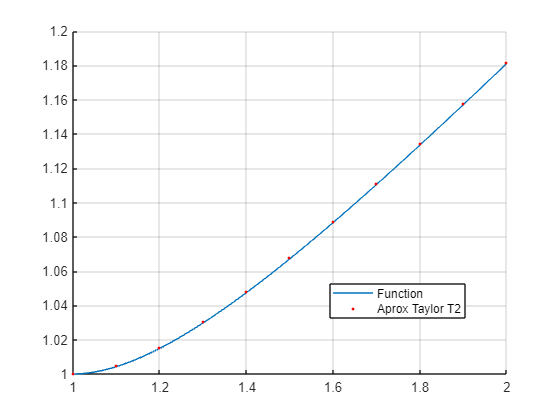

clear
syms f(t, y)

f(t, y) = y/t - (y/t)^2;                                % Función = y'
df(t, y) = diff(f, t) + f(t, y) * diff(f, y);           % Derivada = y''
d2f(t, y) = diff(df,t) + df(t, y) * diff(df, y);        % y'''
d3f(t, y) = diff(d2f, t) + d2f(t, y) * diff(d2f, y);    % y''''

df(t, y) = [f, df, d2f, d3f];

df = matlabFunction(df);
a = 1; b = 2; ya = 1; M = (b - a)/.1;

T4 = taylor(df, a, b, ya, M);

clf('reset')
hold on
fplot(@(t) t ./ (1 + log(t)), [1 2])
plot(T4(:, 1), T4(:, 2), '.r')
legend('Function', 'Aprox Taylor T2', 'location', "best")
grid on
hold off

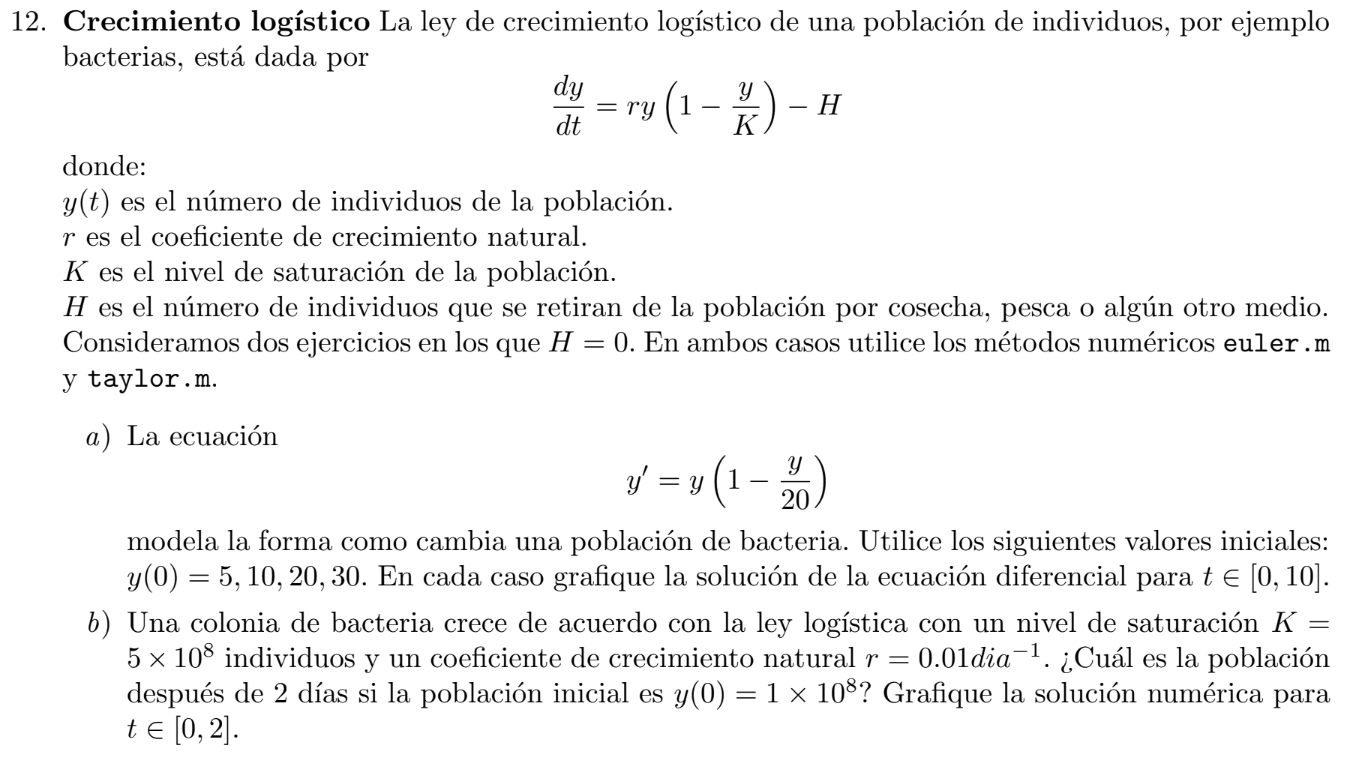

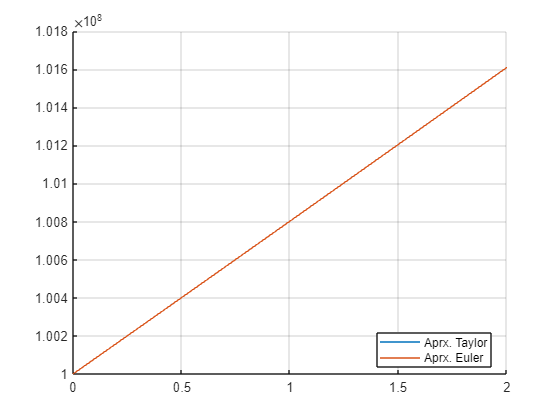

clear
syms f(t, y)

H = 0; K = 5E8; r = .01;

% Definimos las derivadas de y
f(t, y) = r * y * (1 - y / K) - H;
df(t, y) = diff(f, t) + f(t, y) * diff(f, y);
d2f(t, y) = diff(df, t) + df(t, y) * diff(df, y);
d3f(t, y) = diff(d2f, t) + d2f(t, y) * diff(d2f, y);

% Generamos el vector
df(t, y) = [f, df, d2f, d3f];

% Convertimos a funciones de Matlab
f = matlabFunction(f);
df = matlabFunction(df);

a = 0; b = 2; ya = 1E8; M = 100;

E = euler(f, a, b, ya, M);
T4 = taylor(df, a, b, ya, M);

clf('reset')
hold on
plot(T4(:, 1), T4(:, 2), 'DisplayName', 'Aprx. Taylor') 
plot(E(:, 1), E(:, 2), 'DisplayName', 'Aprx. Euler')
legend('Location', "best")
grid on
hold off

### Sistemas de ecuaciones diferenciales de primer Orden

**6) Modelo predador-presa:** Sean $x\left(t\right)$ y $y\left(t\right)$ las poblaciones de conejos y de zorros respectivamente en un tiempo t. El modelo predador-presa consiste en el sistema de ecuaciones diferenciales ordinarias

$x^{\prime } \left(t\right)=A\;x\left(t\right)-B\;x\left(t\right)\;y\left(t\right)$    **(1)**

$y^{\prime } \left(t\right)=C\;x\left(t\right)\;y\left(t\right)-D\;y\left(t\right)$    **(2)**

donde los parámetros tienen el siguiente significado:

***    A: ****Tasa de crecimiento de los conejos.*

***    B: ****Tasa de muerte de los conejos, que depende tanto de la población de*

*    conejos como de la población de zorros.*

***    C: ****Tasa de crecimiento de los zorros, la cual depende de ambas especies.*

***    D: ****Tasa de muerte de los zorros.*

Considere los siguientes conjuntos de parámetros:

**a) **$A=2,\;\;\;B=0,02,\;\;\;C=0,0002,\;\;\;D=0,8$

**a) **$A=1,\;\;\;B=1,\;\;\;C=1,\;\;\;D=1$

Resuelva el sistema por el método de Runge-Kutta de cuarto orden en el intervalo $\left\lbrack 0,10\right\rbrack$con $M=50$

con las siguientes condiciones iniciales:

**a)** $x\left(0\right)=3000\;\textrm{conejos},y\left(0\right)=120\;\textrm{zorros}$

**b)** $x\left(0\right)=5000\;\textrm{conejos},y\left(0\right)=100\;\textrm{zorros}$

Presente sus soluciones por medio de diagramas de fase.

Para esta situación, generaremos diagramas de fase para el primer conjunto de parametros, evaluaremos el comportamiento de las poblaciones, evaluaremos la primera fase, y luego variando las condiciones generales generaremos distintas fases, para ver bien los comportamientos, haremos caso omiso al valor de $M=50$, y asumiremos $M=200$.

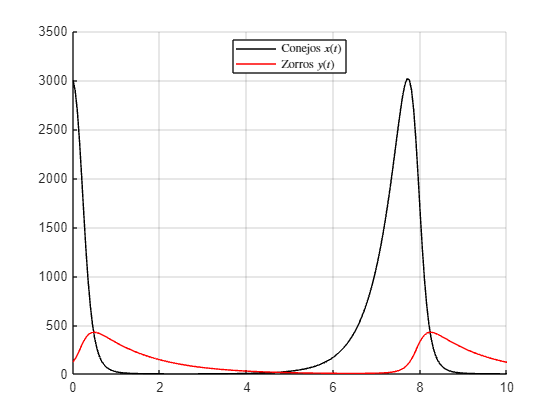

clear

% Inicializamos variables
A = 2; B = 2E-2; C = 2E-3; D = 8E-1;

% Declaramos el sistema
F = @(t, U) [A*U(1) - B*U(1)*U(2), C*U(1)*U(2) - D*U(2)];
t0 = 0; tf = 10; M = 200; Ua = [3e3 12e1];

[t, U] = rks4(F, t0, tf, Ua, M); % Implementamos el método

% Conozcamos el comportamiento de estas funciones
clf('reset')
hold on
plot(t, U(:, 1), 'k', 'DisplayName', 'Conejos $x(t)$')
plot(t, U(:, 2), 'r', 'DisplayName', 'Zorros $y(t)$')
legend('Location','best', 'Interpreter','latex')
grid on
hold off

El comportamiento es claro, a medida que incrementa la población de zorros, la población de conejos se compromete, y el decaimiento de conejos compromete la vida de los zorros.

Ahora veamos este comportamiento en un diagrama de fase:

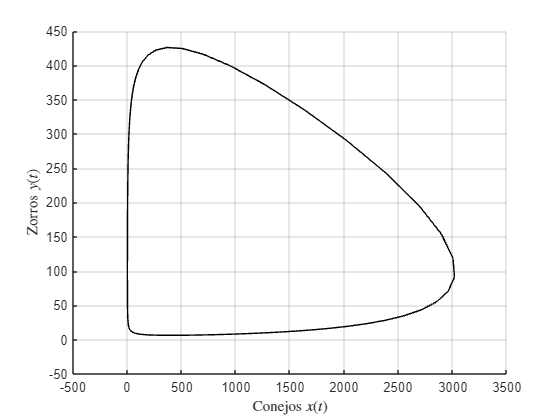

% Conozcamos el comportamiento de las fases
clf('reset')
hold on
plot(U(:, 1), U(:, 2), 'k')
xlabel('Conejos $x(t)$', 'Interpreter','latex')
ylabel('Zorros $y(t)$', 'Interpreter','latex')
xlim([-500 3500])
ylim([-50 450])
grid on
hold off

Veamos que este es el diagrama de fase para el caso particular, veamos como este cambia a medida que se alteran las condiciones iniciales:

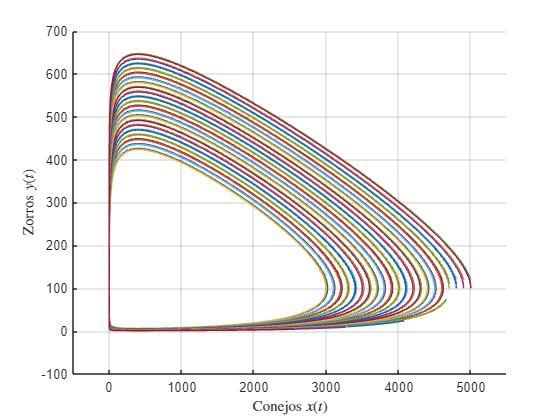

clf('reset')
hold on

% Generamos el ciclo para obtener distintos valores iniciales
for x0 = 3e3:100:5e3
    for y0 = 120:-10:100
        
        Ua = [x0, y0];
        [t, U] = rks4(F, t0, tf, Ua, 1e3); % Resolvemos iterativamente el sistema

        plot(U(:, 1), U(:, 2))
    end
end

xlabel('Conejos $x(t)$', 'Interpreter','latex')
ylabel('Zorros $y(t)$', 'Interpreter','latex')
xlim([-500 5500])
ylim([-100 700])
grid on
hold off

Este es el diagrama de fases para la ecuación diferencial tras la variación de parametros, está representa la variación de poblaciones con respecto a sus poblaciones iniciales, veamos como esta varia tras la variación de parametros:

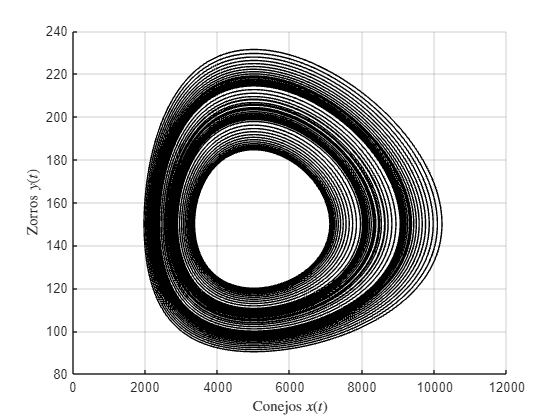

clear
% Inicializamos variables
A = 3;
B = 0.02;
C = 0.0002;
D = 1;

% Declaramos el sistema
F = @(t, U) [A*U(1) - B*U(1)*U(2), C*U(1)*U(2) - D*U(2)];
t0 = 0; tf = 10; M = 200; Ua = [3e3 12e1];

clf('reset')
hold on

% Generamos el ciclo para obtener distintos valores iniciales
for x0 = 3e3:100:5e3
    for y0 = 120:-10:100
        
        Ua = [x0, y0];
        [~, U] = rks4(F, t0, tf, Ua, 1e3); % Resolvemos iterativamente el sistema

        plot(U(:, 1), U(:, 2), 'k')
    end
end

xlabel('Conejos $x(t)$', 'Interpreter','latex')
ylabel('Zorros $y(t)$', 'Interpreter','latex')
grid on
hold off